### This links with `plot_regression_template.mlx` (for comparison between regression and interpolation)

Data 

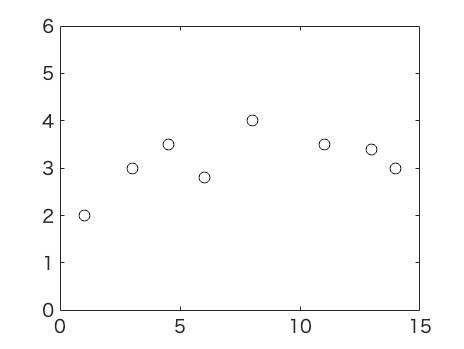

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];

figure
plot(x,y , 'ko')
hold on
axis([0, 15, 0, 6])
hold off

Linear interpolation (points 1 & 8)

xx = [x(1), x(8)]

xx =      1    14


yy = [y(1), y(8)]

yy =      2     3



p1 = polyfit(xx, yy, 1)

p1 =     0.0769    1.9231


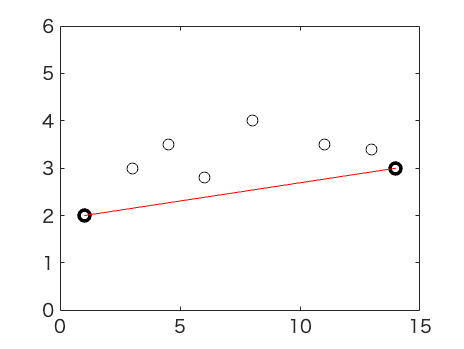


xxx = 1:0.1:14;
yyy1 = polyval(p1, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy1, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

Quadratic polynomial interpolation (points 1,5,8)

xx = [x(1), x(5), x(8)]

xx =      1     8    14


yy = [y(1), y(5), y(8)]

yy =      2     4     3



p2 = polyfit(xx, yy, 2)

p2 =    -0.0348    0.5989    1.4359


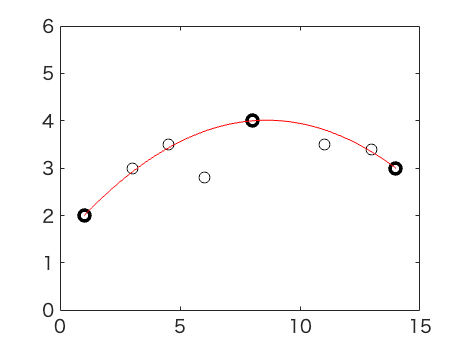


xxx = 1:0.1:14;
yyy2 = polyval(p2, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy2, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

Cubic polynomial interpolation (points 1,3,6,8)

xx = [x(1), x(5), x(6), x(8)]

xx =      1     8    11    14


yy = [y(1), y(5), y(6), y(8)]

yy =     2.0000    4.0000    3.5000    3.0000



p3 = polyfit(xx, yy, 3)

p3 =     0.0035   -0.1148    1.0652    1.0462


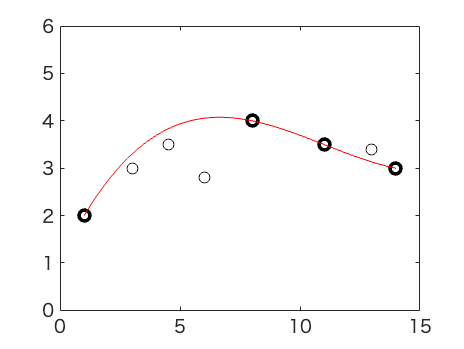


xxx = 1:0.1:14;
yyy3 = polyval(p3, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy3, 'r-')
hold on
axis([0, 15, 0, 6])
hold off

7th-order polynomial interpolation

xx = x

xx =     1.0000    3.0000    4.5000    6.0000    8.0000   11.0000   13.0000   14.0000


yy = y

yy =     2.0000    3.0000    3.5000    2.8000    4.0000    3.5000    3.4000    3.0000



p7 = polyfit(xx, yy, 7)

p7 =    -0.0001    0.0048   -0.1036    1.1597   -7.0728   22.8676  -34.5103   19.6548


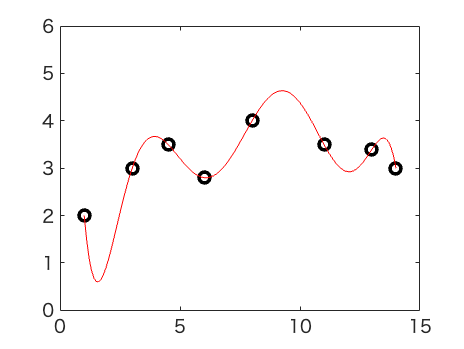


xxx = 1:0.1:14;
yyy7 = polyval(p7, xxx);

figure
plot(xx, yy, 'ko', 'LineWidth', 2)
hold on
plot(x, y, 'ko')
hold on
plot(xxx, yyy7, 'r-')
hold on
axis([0, 15, 0, 6])
hold off


% compare this with the last graph in plot_regression_template.mlx
% both are the same graph